# Идентификация неизвестной системы при помощи LMS-фильтра

#### Загрузка "неизвестной" системы и отображение её АЧХ:

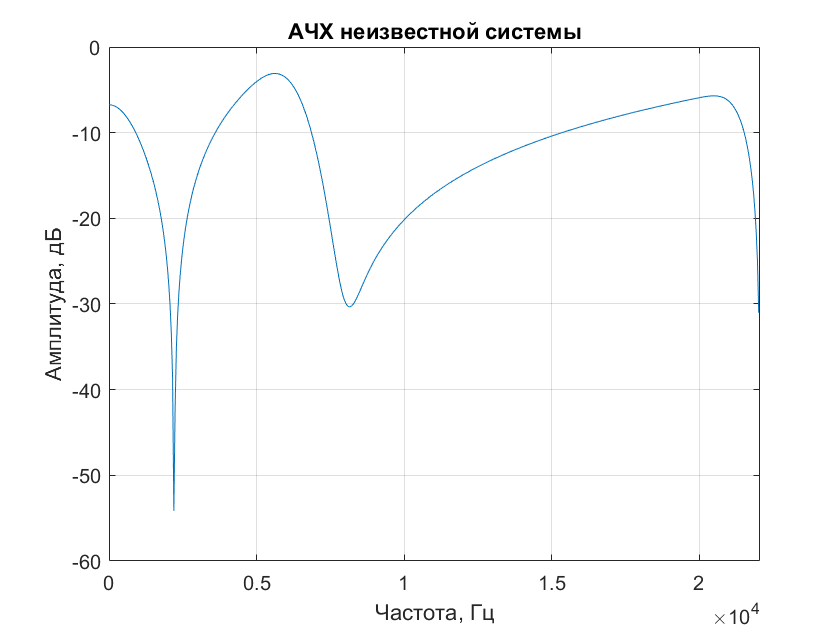

load unknown_filter;
[h1,f] = freqz(unknown_filter,[],fs);
plot(f,20*log10(abs(h1)));
grid on;
xlim([0 fs/2]);
title('АЧХ неизвестной системы');
xlabel('Частота, Гц');
ylabel('Амплитуда, дБ');
hold on;

#### Входной сигнал x[n]:

x = randn(5e4,1);
t = ((0:length(x)-1)/fs)';
sound(x,fs);

#### Выход "неизвестной" системы d[n]:

d = unknown_filter(x);
sound(d,fs);

#### Реалзиация LMS-фильтра, приближение АЧХ системы:

myLMS = dsp.LMSFilter;
myLMS.Length = 64;
myLMS.StepSize = 0.0001;
[y,e,w] = myLMS(x,d);
[h2,f] = freqz(w,1,[],fs);
plot(f,20*log10(abs(h2)));
hold off;

#### Оценка влияния параметра StepSize на скорость схождения:

myLMS = dsp.LMSFilter;
myLMS.Length = 48;
myLMS.StepSize = 0.1;
[y,e,w] = myLMS(x,d);
plot(t,e);
xlim([0 max(t)/2]);
grid on;
title('Схождение ошибки');
xlabel('Время, с');
ylabel('Величина ошибки');
hold on;